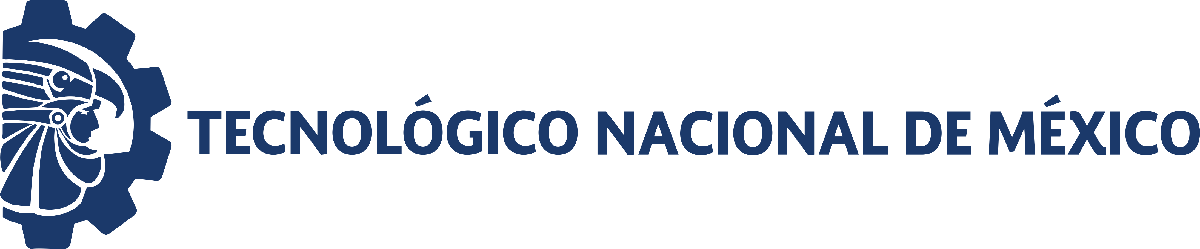                                 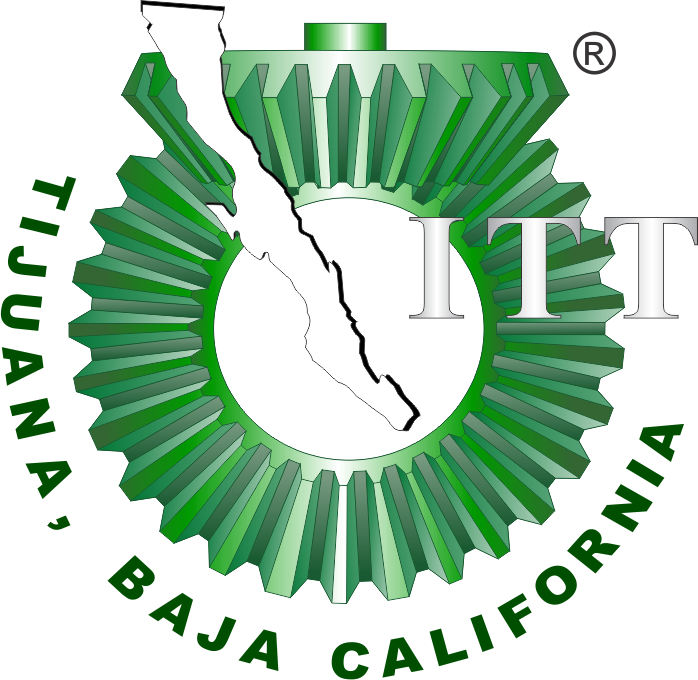

# Práctica 3: Algoritmos de Regresión No Lineal 

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

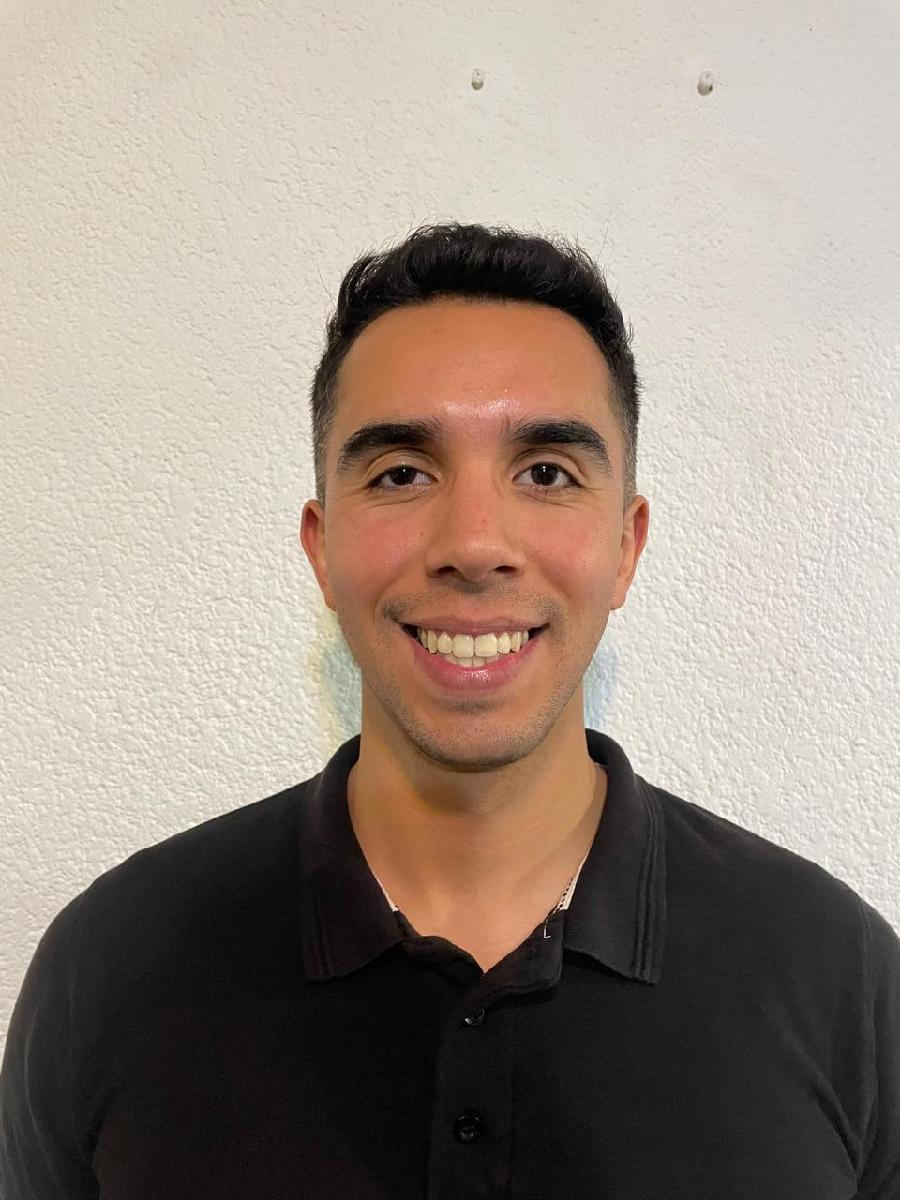

Nombre del alumno: **Carlos Andrés Gil Gárate**

Número de control: **21212743**

Correo institucional: **21212743@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objetivo 

Construir y analizar un modelo mecanicista sobre de la dinámica entre dos variables biológicas.

### Simulation Data

    Time    x1_Sample1    x2_Sample2     xo_Mean  
    ____    __________    __________    __________

      0     6.7923e+07    6.7772e+07    6.7847e+07
      8     1.3379e+08     1.027e+08    1.1825e+08
     16     4.3319e+08    3.3628e+08    3.8474e+08
     24     8.9155e+08    8.6832e+08    8.7993e+08
     32     9.5773e+08    9.8052e+08    9.6912e+08
     40     9.8148e+08    9.9791e+08    9.8969e+08
     48     9.9525e+08    9.9276e+08      9.94e+08
     56     9.8971e+08         1e+09    9.9485e+08
     64          1e+09    9.7521e+08     9.876e+08
     72     9.9383e+08    9.7827e+08    9.8605e+08



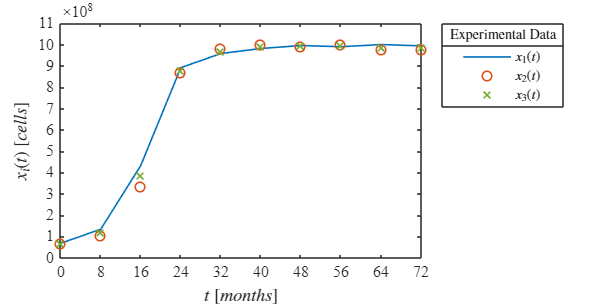

clc; clear; close all; warning('off','all')
sys = readmatrix('data.csv');
to = sys(:,1);
x1o = sys(:,2);
x2o = sys(:,3);
xo = mean([x1o,x2o],2);
T = array2table([to, x1o, x2o, xo], 'VariableNames', {'Time', 'x1_Sample1', 'x2_Sample2', 'xo_Mean'});
disp(T); plotdata(to,x1o,x2o,xo)

xmax = max(xo); %ley de crecimiento sigmoidal

### 1. Nonlinear Regression: Logistic Growth Law

b = 1/xmax; %obtenemos el valor de b una vez despejada. 
k0 = 1E-3;
mdl_logistic = logistic(to,xo,k0,b); x1a = mdl_logistic.Fitted;


Parameter b: 1.0052e-09
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
-Student value: 2.2622
-R-squared: 0.9757
Corrected AIC (n/pars < 40): 388.1464

    Parameters    Estimate       SE          MoE             CI95             pvalue  
    __________    ________    _________    ________    _________________    __________

       "k"        0.16158     0.0095842    0.021681    0.1399    0.18327    4.0727e-08



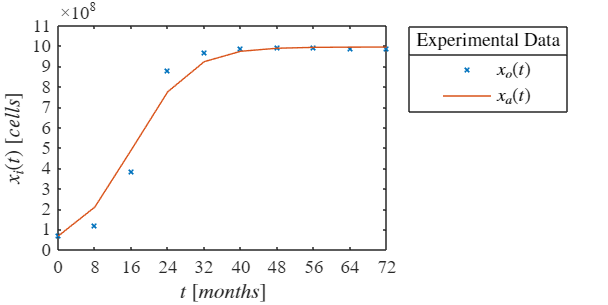

plotfit(to,xo,x1a)

### 2. Nonlinear Regression: Sphere

b = xmax^(-1/3);
k0 = 1E-3;
mdl_allometric = allometric(to,xo,k0,b);


Parameter b: 0.0010017
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value: 2.2622
R-squared: 0.91801
Corrected AIC (n/pars < 40): 400.3094

    Parameters    Estimate      SE       MoE            CI95            pvalue  
    __________    ________    ______    ______    ________________    __________

       "k"         228.81     31.385    70.999    157.82    299.81    4.6116e-05



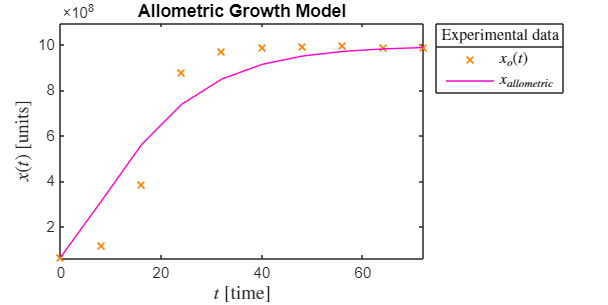

x1a = mdl_allometric.Fitted; 
plotAllometric(to,xo,x1a);

### 3. Nonlinear regression: Fractal

b = xmax^(-1/4);
k0 = 1E-3;
mdl_allometric = allometricf(to, xo, k0, b);


Parameter b: 0.0056307
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value: 2.2622
R-squared: 0.92352
Corrected AIC (n/pars < 40): 399.6135

    Parameters    Estimate      SE       MoE            CI95            pvalue  
    __________    ________    ______    ______    ________________    __________

       "k"         56.982     7.4297    16.807    40.175    73.789    3.0955e-05



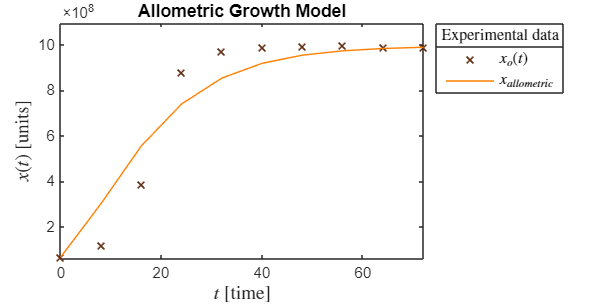

x1a = mdl_allometric.Fitted; 
plotAllometric(to,xo,x1a);

### 4. Nonlinear regression: Gompertz 

b = 1/log(xmax);  
k0 = 1E-3;        
mdl_gompertz = gompertz(to, xo, k0, b);  


Parameter b: 0.048267
Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value: 2.2622
R-squared: 0.9385
Corrected AIC (n/pars < 40): 397.4343

    Parameters    Estimate      SE         MoE            CI95            pvalue  
    __________    ________    _______    _______    ________________    __________

       "k"         1.9245     0.21469    0.48566    1.4389    2.4102    8.8198e-06



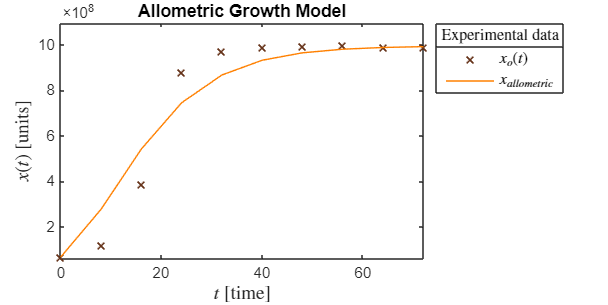

x1a = mdl_gompertz.Fitted; 
plotGompertz(to, xo, x1a);

### 5. Nonlinear regression: Gompertz Simplicity 

b = xmax;  
k0 = 1E-3;        
mdl_gompertz = gomperzS(to, xo, k0, b);  


Sample size (n): 10
Parameters to be estimated (pars): 1
Degrees of freedom: 9
Significance level (alpha): 0.05
t-Student value: 2.2622
R-squared: 0.9385
Corrected AIC (n/pars < 40): 397.4343

    Parameters    Estimate       SE         MoE              CI95             pvalue  
    __________    ________    ________    ________    __________________    __________

       "k"        0.092892    0.010362    0.023441    0.06945    0.11633    8.8203e-06



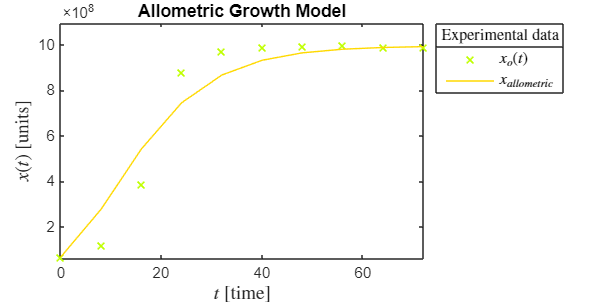

x1a = mdl_gompertz.Fitted; 
plotGompertz(to, xo, x1a);

## 1. Nonlinear Regressions

###     1.1 Nonlinear Regression Algorithm: Logistic Growth Law

function mdl = logistic(to,xo,k0,b)
    function xi = model(k,t)
        dt = 1E-1;
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
        end
        
        function dx = f(x)
            dx = k*x*(1 - b*x);
        end

        xi = zeros(length(t),1);
        
        for j = 1:length(t)
            l = abs(time - t(j)) < 1E-9;
            xi(j) = x(l);
        end
    end

    mdl = fitnlm(to,xo,@model,k0);
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = "k";
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

    fprintf(['\nParameter b: ',num2str(b)])
    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\n-Student value: ', num2str(tval)])
    fprintf(['\n-R-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    
    disp(Results)
end

###     1.2 Nonlinear regression algorithm: Allometric Sphere Growth Law

function mdl = allometric(to,xo,k0,b)
    function xi = model(k,t)
        dt = 1E-1;
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
        end
        
        function dx = f(x)
            dx = k * x^(2/3) * (1 - b * x^(1/3));
        end

        xi = zeros(length(t),1);
        
        for j = 1:length(t)
            l = abs(time - t(j)) < 1E-9;
            xi(j) = x(l);
        end
    end

    mdl = fitnlm(to,xo,@model,k0);
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = "k";
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

    fprintf(['\nParameter b: ', num2str(b)])
    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    
    disp(Results)
end

###     1.3 Nonlinear regression algorithm: Allometric Fractal Growth Law

function mdl = allometricf(to,xo,k0,b)
    function xi = model(k,t)
        dt = 1E-1;
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
        end
        
        function dx = f(x)
            dx = k*x^(3/4)*(1 - b*x^(1/4));
        end

        xi = zeros(length(t),1);
        
        for j = 1:length(t)
            l = abs(time - t(j)) < 1E-9;
            xi(j) = x(l);
        end
    end

    mdl = fitnlm(to,xo,@model,k0);
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = "k";
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

    fprintf(['\nParameter b: ', num2str(b)])
    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    
    disp(Results)
end

###     1.4 Nonlinear regression algorithm: Gompertz Growth Law

function mdl = gompertz(to, xo, k0, b)
    function xi = model(k, t)
        dt = 1E-1;
        time = (0:dt:max(t))';  
        n = round(max(t) / dt);  
        x = zeros(length(time), 1); 
        x(1) = xo(1);  

        for i = 1:n
            fx = f(x(i), k, b);
            xn = x(i) + fx * dt;
            fxn = f(xn, k, b);
            x(i + 1) = x(i) + (fx + fxn) * dt / 2;  
        end
        
        xi = zeros(length(t), 1);
        for j = 1:length(t)
            l = abs(time - t(j)) < 1E-9;
            xi(j) = x(l);
        end
    end

    function dx = f(x, k, b)
        dx = k * x * (1 - b * log(x));  
    end

    mdl = fitnlm(to, xo, @model, k0);  

    Estimate = table2array(mdl.Coefficients(:, 1));
    SE = table2array(mdl.Coefficients(:, 2));
    pvalue = table2array(mdl.Coefficients(:, 4));
    alpha = 0.05;
    CI95 = coefCI(mdl, alpha);  
    dof = mdl.DFE;  
    tval = tinv(1 - alpha / 2, dof);  
    MoE = SE * tval;  
    Parameters = "k";  
    Results = table(Parameters, Estimate, SE, MoE, CI95, pvalue);  

    fprintf(['\nParameter b: ', num2str(b)]);
    fprintf(['\nSample size (n): ', num2str(numel(xo))]);
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))]);
    fprintf(['\nDegrees of freedom: ', num2str(dof)]);
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)]);
    fprintf(['\nt-Student value: ', num2str(tval)]);
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)]);
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc), '\n\n']);
    
    disp(Results);  
end

###     1.5 Nonlinear regression algorithm: Gompertz Simplicity Growth Law

function mdl = gomperzS(to,xo,k0,b)
    function xi = model(k,t)
        dt = 1E-1;
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = xo(1);

        for i = 1:n
            fx = f(x(i));
            xn = x(i) + fx*dt;
            fxn = f(xn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
        end

        function dx = f(x)
            dx = k * x * log ((b)/(x));
        end

        xi = zeros(length(t),1);

        for j = 1:length(t)
            k = abs(time - t(j)) < 1E-9;
            xi(j) = x(k);
        end
    end 

    mdl = fitnlm(to,xo,@model,k0);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE;
    tval = tinv(1-alpha/2,dof);
    MoE = SE*tval;
    Parameters = "k";
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);
    
    fprintf(['\Parameters (n): ', num2str(numel(b))]) 
    fprintf(['\nSample size (n): ', num2str(numel(xo))]) 
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(k0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    disp(Results)
end


### 2. Functions 

#### 2.1 Plot Data and observerd Data 

function plotdata(to,x1o,x2o,xo)
    blu = [0 0.4470 0.7410];  % Azul
    nrj = [0.8500 0.3250 0.0980];  % Naranja
    amr = [0.9290 0.6940 0.1250];  % Amarillo
    vrd = [0.4660 0.6740 0.1880];  % Verde
    mor = [0.4940 0.1840 0.5560];  % Morado

    set(figure(1),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,10])
    set(gca,'FontName','Times New Roman')
    fontsize(10,'points')
    NGS = [98,227,218; 98,154,227; 132,79,232; 98,227,174;]/255;
    hold on; box on; grid off; colororder(NGS)

    plot(to,x1o,'-','LineWidth',1,'Color',blu)
    plot(to,x2o,'o','LineWidth',1,'Color',nrj)
    plot(to,xo,'x','LineWidth',1,'Color',vrd)
    xlabel('$t$ $[months]$','Interpreter','latex')
    ylabel('$x_i(t)$ $[cells]$','Interpreter','latex')
    L = legend('$x_1(t)$','$x_2(t)$','$x_3(t)$');
    set(L,'Interpreter','latex','Location','NorthEastOutside')
    title(L,'Experimental Data')
    xlim([0 72]); xticks(0:8:72)
    ylim([0 11E8]); yticks(0:1E8:11E8)
    exportgraphics(gcf,'exponential growth.pdf','ContentType','vector')
end

#### 2.2 Plotfit and observerd Data 

function plotfit(t,xo,xa)
    blu = [0 0.4470 0.7410];  % Azul
    nrj = [0.8500 0.3250 0.0980];  % Naranja
    amr = [0.9290 0.6940 0.1250];  % Amarillo
    vrd = [0.4660 0.6740 0.1880];  % Verde
    mor = [0.4940 0.1840 0.5560];  % Morado
    naj = [0.8500 0.3250 0.0980];  % Naranja (repetido)

    set(figure(),'Color','w')
    FS = 12; 
    set(gcf,'Units','Centimeters','Position',[2,2,20,10])
    hold on; box on; grid off;
    plot(t,xo,'x','LineWidth',1,'MarkerSize',4,'Color',blu)
    plot(t,xa,'-','LineWidth',0.5,'MarkerSize',2,'Color',naj)
    xlabel('$t$ $[months]$','Interpreter','latex','FontSize',FS)
    ylabel('$x_i(t)$ $[cells]$','Interpreter','latex','FontSize',FS)
    xlim([0 72]); xticks(0:8:72)
    ylim([0 11E8]); yticks(0:1E8:11E8)

    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','FontSize',FS,'Location','NorthEastOutside')
    title(L,'Experimental Data')
    set(gca,'FontName','Times New Roman','FontSize',FS)
end 

### 2.3 Plot Allometric and observed data

function plotAllometric(to, xo, x1a)
    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.85, 0.00; 
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];
    rng('shuffle'); 
    indices = randperm(size(Mecambiareaindustrial,1), 3); 
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
    
    figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 2, 20, 10]);
    hold on; box on; grid off;    
    
    plot(to, xo, 'x', 'Color', c1, 'LineWidth', 1, 'DisplayName', '$x_o(t)$');
    plot(to, x1a, '-', 'Color', c2, 'LineWidth', 0.5, 'DisplayName', '$x_{allometric}$');
    
    xlabel('$t$ [time]', 'Interpreter', 'latex', 'FontSize', 12);
    ylabel('$x(t)$ [units]', 'Interpreter', 'latex', 'FontSize', 12);
    
    leg = legend('Interpreter', 'latex', 'Location', 'NorthEastOutside', 'FontSize', 10);
    title(leg, 'Experimental data');
    title('Allometric Growth Model', 'FontSize', 11); 
    
    xlim([min(to), max(to)]);
    ylim([min(xo)*0.9, max(xo)*1.1]);
    
    exportgraphics(gcf, 'allometric_fit.pdf', 'ContentType', 'vector');
end

### 2.4 Plot Gompertz and observed data 

function plotGompertz(to, xo, x1a)
    Mecambiareaindustrial = [
        0.60, 0.00, 0.00;  
        0.75, 1.00, 0.00;  
        0.00, 0.75, 1.00;  
        0.50, 0.00, 0.75;
        1.00, 0.50, 0.00;  
        0.40, 0.20, 0.10;  
        1.00, 0.00, 0.80;  
        1.00, 0.85, 0.00; 
        0.00, 0.85, 0.65;  
        0.30, 0.45, 0.60   
    ];
    rng('shuffle'); 
    indices = randperm(size(Mecambiareaindustrial,1), 3); 
    c1 = Mecambiareaindustrial(indices(1), :);
    c2 = Mecambiareaindustrial(indices(2), :);
        figure('Color', 'w', 'Units', 'Centimeters', 'Position', [2, 2, 20, 10]);
    hold on; box on; grid off;    
        plot(to, xo, 'x', 'Color', c1, 'LineWidth', 1, 'DisplayName', '$x_o(t)$');
        plot(to, x1a, '-', 'Color', c2, 'LineWidth', 0.5, 'DisplayName', '$x_{allometric}$');
        xlabel('$t$ [time]', 'Interpreter', 'latex', 'FontSize', 12);
    ylabel('$x(t)$ [units]', 'Interpreter', 'latex', 'FontSize', 12);
    
    leg = legend('Interpreter', 'latex', 'Location', 'NorthEastOutside', 'FontSize', 10);
    title(leg, 'Experimental data');
    title('Allometric Growth Model', 'FontSize', 11); 
        xlim([min(to), max(to)]);
    ylim([min(xo)*0.9, max(xo)*1.1]);
        exportgraphics(gcf, 'allometric_fit.pdf', 'ContentType', 'vector');
end